# FMCW Radar.- Northe, Velez, Woerner

## Experimental task 1: VCO Characteristic curve

## 4.1.- VCO Characteristic Curve

#### 1.- Connect the "User 1" port, whose output frequency is 1/(16x4096) = 1/65536 of the output frequency

#### of VCO fVCO, to an oscilloscope, change the control voltage V from 1.0V to 7.0V with a

#### step of 0.4 V using "T1_Control_Voltage.exe" and record the frequency for for each step in a Table.

#### 2.- Taking into account that a frequency divider circuit with a factor of 4096 is used here, calculate

#### the output frequency fVCO at VCO’s RFOUT port and record them in the third row of

Define control voltage values

clc, clear;
V = 1.0:0.4:7.0; % Voltage steps from 1.0V to 7.0V in 0.4V steps

Preallocate arrays for measured frequency (fr) and VCO frequency (f_VCO)

fr = zeros(size(V));     % Frequency measured at User 1 port
fVCO = zeros(size(V));   % VCO output frequency (calculated)

Measured Frequency Values (in kHz):

fr = [358.7, 361.62, 364.04, 366.17, 368.19, 370.16, 371.88, 373.55, 375.09, 376.65, 378.12, 379.58, 380.86, 382.14, 383.3, 384.9];

Calculate VCO frequency

According to the instruction: f_r = f_VCO / 65536 -> f_VCO = f_r * 65536

fVCO = (fr * 1e3 * 65536)/1e9; %result in GHz

Display Results in Table

T = table(V', fr', fVCO', 'VariableNames', {'V', 'f_r_kHz', 'f_VCO_GHz'});
disp('Table 4.1: Measured results of the VCO''s characteristic');

Table 4.1: Measured results of the VCO's characteristic


disp(T);

     V     f_r_kHz    f_VCO_GHz
    ___    _______    _________

      1     358.7      23.508  
    1.4    361.62      23.699  
    1.8    364.04      23.858  
    2.2    366.17      23.997  
    2.6    368.19       24.13  
      3    370.16      24.259  
    3.4    371.88      24.372  
    3.8    373.55      24.481  
    4.2    375.09      24.582  
    4.6    376.65      24.684  
      5    378.12       24.78  
    5.4    379.58      24.876  
    5.8    380.86       24.96  
    6.2    382.14      25.044  
    6.6     383.3       25.12  
      7     384.9      25.225  



## Plot of the calculated VCO Characteristic Curve

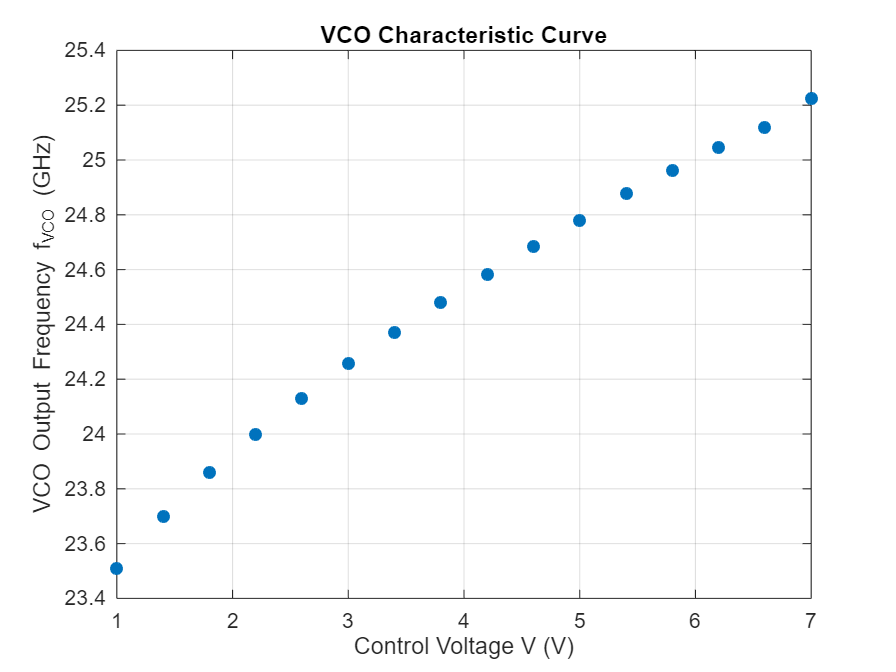

 figure;
 plot(V, fVCO, '*', 'LineWidth', 2, 'LineStyle', 'none');
 xlabel('Control Voltage V (V)');
 ylabel('VCO Output Frequency f_{VCO} (GHz)');
 title('VCO Characteristic Curve');
 grid on;

#### 3.- Depict the VCO’s characteristic curve fVCO (V ) using MATLAB (use interp1() for interpolation. and choose spline for interpolation method, attach the source code to your final report).

Calculate Interpolated VCO frequency

stepsize = 0.01;
V_fine = 1.0:stepsize:7.0;
f_VCO_interpol = interp1(V, fVCO, V_fine, 'spline');

Calculate Ideal Interpolation

Offset_min = 0.07;
Offset_max = 0.01;
Vmin = min(f_VCO_interpol)+ Offset_min;
Vmax = max(f_VCO_interpol)+ Offset_max;
dist = Vmax-Vmin;
dim = size(V_fine);
steps = dist / dim(2);
f_VCO_ideal = Vmin:steps:Vmax;
stepsize2 = 6 / 601;
V_fine_2 = 1:stepsize2:7;

Plot interpolated VCO Characteristic Curve

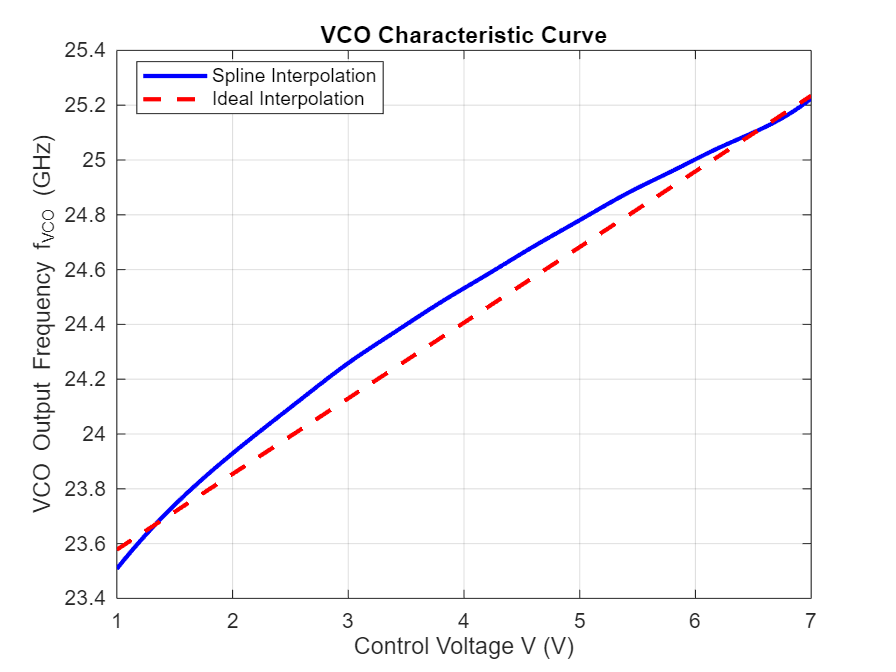

figure;
plot(V_fine, f_VCO_interpol, 'b-', 'LineWidth', 2);      
hold on;
plot(V_fine_2, f_VCO_ideal, 'r--', 'LineWidth', 2);
hold off;
xlabel('Control Voltage V (V)');
ylabel('VCO Output Frequency f_{VCO} (GHz)');
title('VCO Characteristic Curve');
legend('Spline Interpolation', 'Ideal Interpolation','Location', 'best');
grid on;

legend(["Spline Interpolation", "Ideal Interpolation"], "Position", [0.1530 0.8305 0.2750, 0.0774])

#### 4.- Specify the control voltage V_C for a triangular FMCW RADAR using measured VCO Curve

Given:

f_0 = 24 GHz

B = 500 MHz

f_DA = 100 kHz  -> 500MHz / 100 kHz = 5000

T_sweep = 10 ms

Get relevant voltage range

% Frequecy range in GHz
f_min = 23.75;
f_max = 24.25;
T_sweep = 10; %ms

% mask frequencies of the relevant region
%mask = f_VCO_ideal((f_VCO_ideal >= f_min) & (f_VCO_ideal <= f_max))
%mask = (f_VCO_ideal >= f_min) & (f_VCO_ideal <= f_max)

% Choose the related voltages to the frequencies
%V_selected = V_fine_2(mask)

df = 0.0001;         % 100 kHz = 0.0001 GHz

% Step 2: Create desired frequency array with 100kHz steps
f_uniform = f_min:df:f_max;

% Step 3: Invert the interpolation: find V values for desired f values
% Use interp1 with frequency as x and voltage as y
%V_interp = interp1(f_VCO_ideal, V_fine_2, f_uniform, 'spline');
V_interp = interp1(f_VCO_interpol, V_fine, f_uniform, 'spline');

% step 4: remove any NaNs due to extrapolation
valid_idx = ~isnan(V_interp);
V_interp = V_interp(valid_idx);
V_full_sweep = [V_interp flip(V_interp(1:end-1))];
f_uniform = f_uniform(valid_idx);
timestep = T_sweep / 5000;
time = 0:timestep:2*T_sweep;

Plot the V_c(t) curve        

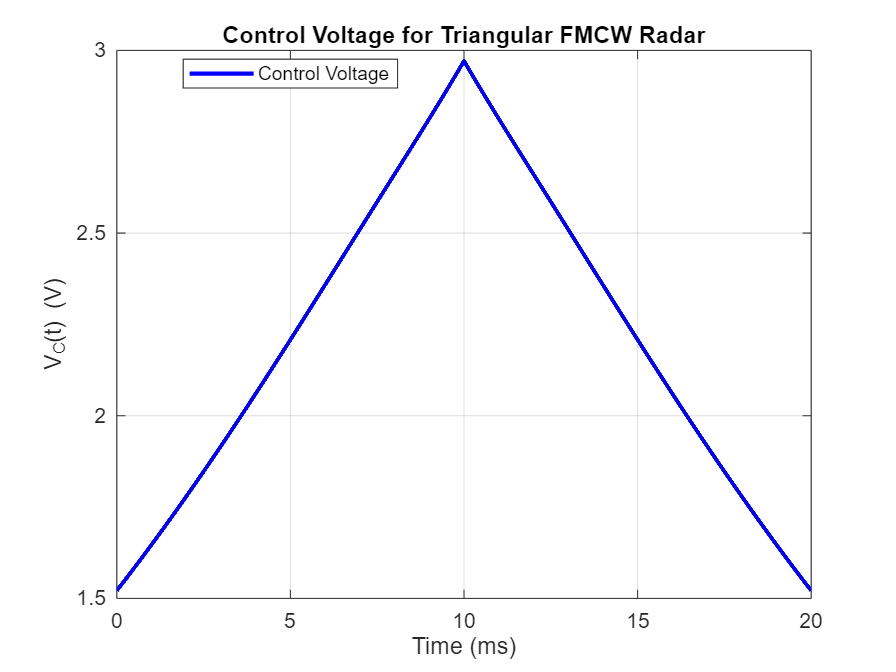

figure;
plot(time, V_full_sweep, 'b-', 'LineWidth', 2);      
xlabel('Time (ms)');
ylabel('V_C(t) (V)');
title('Control Voltage for Triangular FMCW Radar');
legend('Control Voltage', 'Location', 'best');
grid on;

#### 5.- Why is the VCO’s characteristic curve needed before the radar measurement?

Because the VCO output frequency is not perfectly linear to it's input voltage. Therefore we have to measure it's characteristic curve and map the input voltage values to the actually generated frequencies to ensure, that the frequency sweep we generate behaves the way we want.

## Experimental task 2: Distance Measurement

A corner reflector is placed in front of the radar (1.5 m < r < 5 m). The parameters of a triangular FMCW radar are given as follows: $f_0$ = 24 GHz, B = 1 GHz, Tsweep = 10 ms.

#### 1.- Estimate the minimal AD sampling frequency fs for this experiment according to the Nyquist sampling criterion (the real sampling frequency should be 1.3 times of the theoretical one). Examine whether all sampling points can be used or whether there is an overlap between up- and down-sweep. Choose the sampling frequency in a way that the Nyquist criterion is fulfilled and a Fast Fourier Transform can be used.

The following snippet computes the required f_s_min and f_s_min_fft to satisfy these conditions:

clear; clc;

c0 = physconst('LightSpeed');
fc = 24e9;       % [Hz]
r = 5;           % [m]
B = 1e9;         % [Hz]
T_sweep = 10e-3; % [s]

gamma = B / T_sweep;
f_b_max = (2 * gamma * r) / c0;

f_s_min = 2 * f_b_max * 1.3

f_s_min = 8.6727e+03

f_s_fft_min = f_s_min * 2

f_s_fft_min = 1.7345e+04

#### 4.2.2 Range Estimation $r\;$from $s_{\mathrm{if}}$

load("ws_task2.mat");

c0 = physconst('LightSpeed');
f_c     = 24e9;     % [Hz]
T_sweep = 10e-3;    % [s]

BW = fmax - fmin;
gamma = BW / (T_sweep);

% n samples which are needed for one sweep
N = round(T_sweep * fs);
fft_length = 2^nextpow2(N);

% 4 * for smooth vel
fft_length = 4 * fft_length

fft_length = 4096

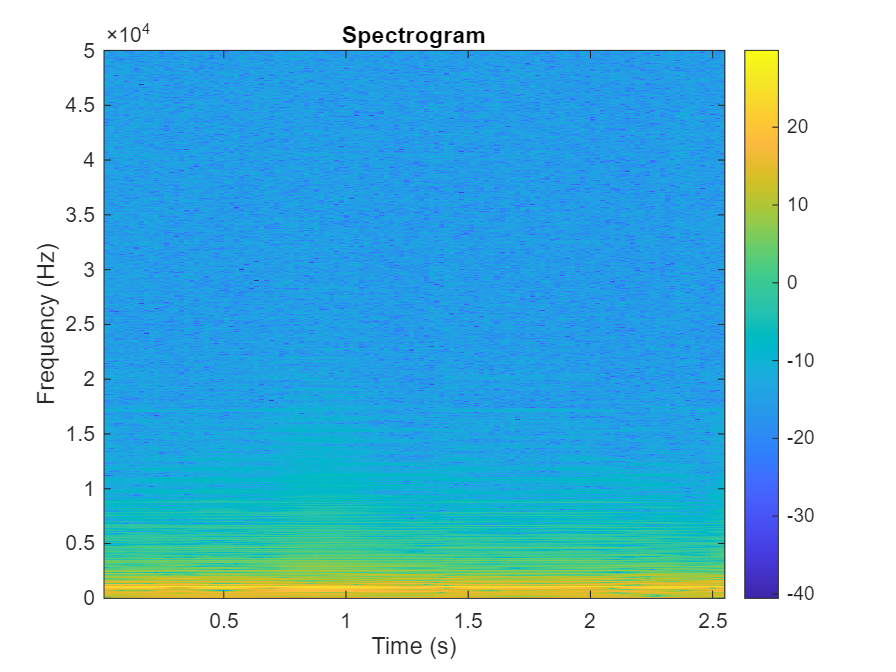

[s, f, t] = make_spectrogram(sif, fs, fft_length);

[~, time_slices] = size(s);

v_r = zeros(1, time_slices);
range = zeros(1, time_slices);

for t = 1:time_slices
    % for each spectrum of the spectrogram
    % find the two local max (try to avoid finding two adjacent bins)
    % then use f_b + f_d formulas

    spec = s(:, t);
    spec = abs(spec);

    max_mask = islocalmax(spec);              
    peak_vals = spec(max_mask);  

    % for debugging the peaks
    %plot_spectrum_with_peaks(spec, max_mask, fs);
    
    if numel(peak_vals) >= 2
        [~, idx_sorted] = maxk(peak_vals, 2);         
        peak_indices_in_spec = find(max_mask);    
        top2_indices = peak_indices_in_spec(idx_sorted);
        top2_values = spec(top2_indices);          
    elseif numel(peak_vals) == 1
        top2_indices = find(max_mask);
        top2_values = spec(top2_indices);
    else
        top2_indices = [];
        top2_values = [];
    end

    top2_indices = top2_indices * fs / fft_length;

    f_b = 0.5 * (top2_indices(1) + top2_indices(2));
    f_d = 0.5 * (top2_indices(1) - top2_indices(2));

    range(t) = c0 / (2 * gamma) * f_b;
    v_r(t)   = c0 / (2 * f_c)   * f_d;
end

r_min = min(range);
r_max = max(range);
v_min = min(v_r);
v_max = max(v_r);

fprintf('Raw:\n');

Raw:


fprintf('Range:   Min = %.3f m, Max = %.3f m\n', r_min, r_max);

Range:   Min = 1.446 m, Max = 1.665 m


fprintf('Velocity: Min = %.3f m/s, Max = %.3f m/s\n', v_min, v_max);

Velocity: Min = -0.305 m/s, Max = 0.610 m/s



range_filtered = sgolayfilt(range, 3, 11);
v_r_filtered = sgolayfilt(v_r, 3, 11);

r_min_f = min(range_filtered);
r_max_f = max(range_filtered);

v_r_min_f = min(v_r_filtered);
v_r_max_f = max(v_r_filtered);

fprintf('\nFiltered:\n');


Filtered:


fprintf('Range:   Min = %.3f m, Max = %.3f m\n', r_min_f, r_max_f);

Range:   Min = 1.447 m, Max = 1.669 m


fprintf('Velocity: Min = %.3f m/s, Max = %.3f m/s\n', v_r_min_f, v_r_max_f);

Velocity: Min = -0.371 m/s, Max = 0.688 m/s


fprintf('For Q. 4.2.2: %.3f m\n', mean(range_filtered)); %Computation for estimating the average range

For Q. 4.2.2: 1.528 m


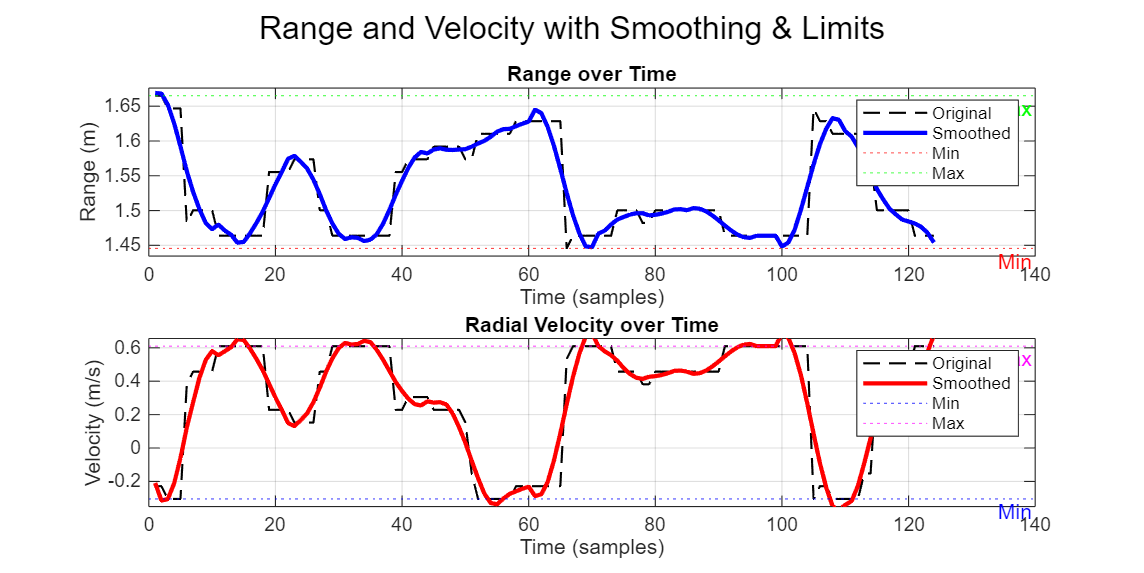

% Time or index axis
t = 1:length(range);

% Create figure
figure('Color', 'w', 'Position', [100, 100, 1000, 500]);

% === Plot 1: Range ===
subplot(2,1,1);
plot(t, range, '--k', 'LineWidth', 1); hold on;
plot(t, range_filtered, 'b', 'LineWidth', 2);
yline(r_min, ':r', 'Min', 'LabelVerticalAlignment','bottom');
yline(r_max, ':g', 'Max', 'LabelVerticalAlignment','bottom');
grid on;
title('Range over Time');
xlabel('Time (samples)');
ylabel('Range (m)');
legend('Original', 'Smoothed', 'Min', 'Max');
ylim([r_min - 0.05*(r_max - r_min), r_max + 0.05*(r_max - r_min)]);

% === Plot 2: Velocity ===
subplot(2,1,2);
plot(t, v_r, '--k', 'LineWidth', 1); hold on;
plot(t, v_r_filtered, 'r', 'LineWidth', 2);
yline(v_min, ':b', 'Min', 'LabelVerticalAlignment','bottom');
yline(v_max, ':m', 'Max', 'LabelVerticalAlignment','bottom');
grid on;
title('Radial Velocity over Time');
xlabel('Time (samples)');
ylabel('Velocity (m/s)');
legend('Original', 'Smoothed', 'Min', 'Max');
ylim([v_min - 0.05*(v_max - v_min), v_max + 0.05*(v_max - v_min)]);

sgtitle('Range and Velocity with Smoothing & Limits');

fprintf('Range Resolution: %.3f m\n', c0 / (2 * 1e9));

Range Resolution: 0.150 m


$r=1\ldotp 528m$ computed as the average of the range.

**Explanation**:

The range is estimated using a frequency-domain approach based on the spectrogram of the IF signal. For each sweep, the FFT is computed to obtain the beat frequency spectrum. The two strongest peaks in the magnitude spectrum are detected, and their average frequency is taken as the beat frequency�. The range is then calculated using the standard FMCW radar equation.

We observe that the range is correctly obtained from the measurements permoded with the FMCW radar. However, the measurements indicate that the position of the target was not constant, but rather there was a small movement range during the measurements of +- 10 cm w.r.t. the mean position of 1.5 meters. This can be explained by slight movements from the person holding the target, this small fluctuation could cause, after the whole procedure of recovering the range that the estimation falls into the wrong bin, and therefore the error causes the estimation to be off by +-15cm, which is what we observe on our plots.

#### 4.2.3 Indicate the false target

The false target can be seen by the strong peak in the $s_{\textrm{if}}$ signal in the frequency domain.

Here the strongest peak is in the DC/0-Hz Bin. This has to be ignored in the signal processing as this signal is the result from TX-RX coupling. The coupled signal has the strongest signal power and almost no phase shift and no doppler shift. Therefore the result from the mixing process is $f_{TX} - f_{RX} = 0$ and $f_{TX} + f_{Rx} $ and the both frequencies.

But only the 0Hz results is visible due to image filtering after the mixing stage.

#### 4.2.4 Theoretical vs. Measured SNR


$$SNR_{Theo} = 78.21 dB$$



$$SNR_{Meas} = 50.21 dB$$


For the theoretical SNR the calculation can be found: MWE_Lab_Noise_Est.m

For the measured SNR the calculation can be found: MWE_Lab_Noise_measure.m